# 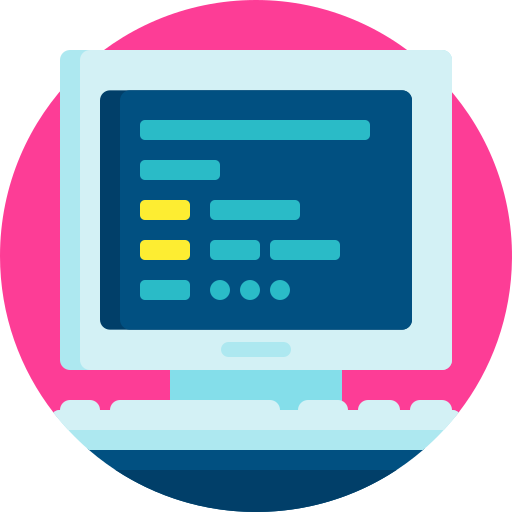

# Virtual Lab 1: The mass-spring-damper system

**Chapter 2-3**

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output on Right`.

- This script has been sectioned off — you can use `Run Section `(CMD/CNTL+ENTER) instead of` Run `when in a particular section. This will only evaluate code in the section. 

- This virtual lab requires the following `MATLAB` toolboxes: Control Systems Toolbox, Symbolic Math Toolbox.

- You can use the `help` function to get information on a function within the `MATLAB Command Window`, e.g. `help laplace`.

## Transfer Function Definition

Consider a dynamic system with a single input function $u(t)$ and a single output function$y(t)$:

    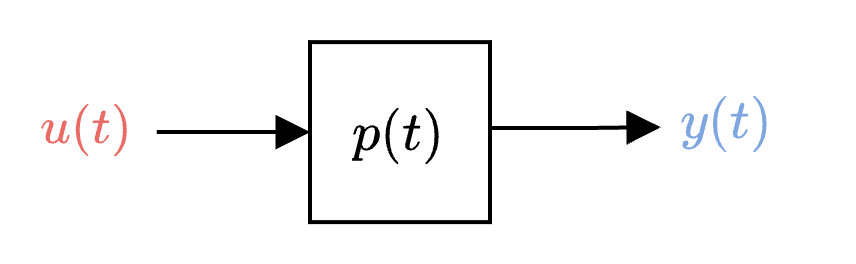

This is known as a **SISO** (Single Input Single Output) system. In general, the system $p(t)$ can be defined through a differential equation. We can alternatively define a time-parameterised $p(t)$ that directly describes the system behaviour, but our relationship between $y(t)
$ and $u(t)$ will be described by the convolution operation of $y(t)=p(t)*u(t).$

A powerful and transparent alternative is the **transfer function, **which is defined as

    $P(s) = \frac{Y(s)}{U(s)}$,

and describes the ratio of the Laplace transform of the output signal,$Y(s) = \mathcal{L}\{y(t)\}$, to the Laplace transform of the input signal, $U(s) = \mathcal{L}\{u(t)\}$. The transfer function $P(s)$ maps inputs $U(s)$ to outputs $Y(s)$:

     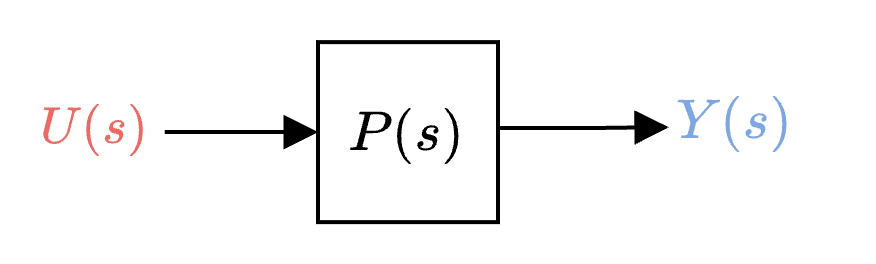

So, assuming that we can find the ratio of $Y(s)$ and $U(s)$, we can always mathematical define how our system behaves. Understanding what $P(s)$ actually means to us will be explored in future Virtual Labs, but this assessment will make a start at understanding things.

### Laplace transform derivation

The Laplace transform of a locally integrable function $f(t)$ is 

    $F(s) = \mathcal{L}\{f(t)\} =\int_{0}^{\infty} f(t) e^{-st} \ dt$,

The corresponding inverse Laplace transform is denoted as

    $f(t) = \mathcal{L}^{-1} \{ F(s) \}$.

Inverse Laplace transforms (and forward Laplace transforms, for that matter) are usually found by appealing to a transform table. The formal definition of the inverse Laplace transform is rarely used and so is not discussed here. 

### Solving differential equations using the Laplace transform

If we are given (or can derive) linear differential equations that describe our system, we can make use of the Laplace transform to find the relationship between our input and output signals. Importantly, we need to know what our initial conditions are in order to apply the appropriate transform.

Recall that the Laplace transform of a time derivative can be computed through integration by parts (*we will cover this in more detail in upcoming lectures*):

    
$$\begin{array}{rl}
\mathcal{L}\{f'(t)\} &= \int_{0}^{\infty}  \dot{f}(t) e^{-st} \ dt
\\
&= \left. f(t) e^{-st} \ \right\vert_0^\infty - \int_{0}^{\infty}  f(t) \left( -s  e^{-st}) \ dt
\\
&= - f(0) + sF(s).
\end{array}$$


If we are able to set (by adjusting our axes if need be) our initial condition, $f(0)$, to zero, we end up with the simplified result of 


$$\mathcal{L}\{\frac{d}{dt}f(t)\}=sF(s).$$
  

If our system is completely at rest (all the various derivatives equal to zero at $t=0$), then we can extend the above result to


$$\mathcal{L}\{\frac{d^k}{dt^k}f(t)\}=s^kF(s).$$
  

Given the relationships above, and assuming our initial conditions have been set to zero, we can convert any differential equation of the form


$$b_0y(t)+b_1\frac{d}{dt}y(t)+b_2\frac{d^2}{dt}{y}(t)+...+b_n\frac{d^n}{dt}y(t) =
a_0u(t)+a_1\frac{d}{dt}u(t)+a_2\frac{d^2}{dt}{u}(t)+...+a_m\frac{d^m}{dt}u(t)$$


into a corresponding equation that is solely a function of the Laplace operator $s$

$b_0Y(s)+b_1sY(s)+b_2s^2{Y}(s)+...+b_ns^nY(s) =
a_0U(s)+a_1sU(s)+a_2s^2{U}(s)+...+a_ms^mU(s)$.

## The mass-spring-damper system

The mass-spring-damper system below is dynamically forced by an arbitrary function $u(t)=F(t)$, with a mass of $m$, a damping coefficient of $c$, and a spring constant of $k$. 

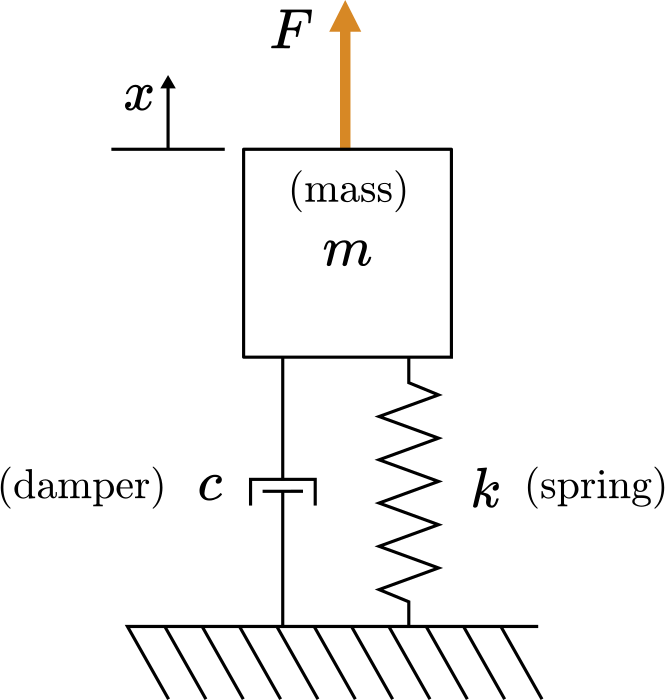

The differential equation for a mass-spring-damper system is given as 

$m\ddot{x}(t)+c\dot{x}(t)+kx(t)+mg=u(t)$.

At steady-state, our system will come to rest and our equation above will balance to

$kx(t_\infty)+mg=u(t_\infty)$,

where $t_\infty$ is the time it takes for the system to come to complete rest. If we were to apply a forcing function such that $u(t_\infty)=0$, for example where we pull the mass upwards and then let go, then the equation above balances to

$kx(t_\infty)+mg=0$,

which implies that

$kx(t_\infty)=-mg$.

In other words, our spring is now loaded in steady state, based on the gravitational weight, with the steady-state location of the mass sitting lower than the untensioned spring height. If we now choose this steady-state position, $x(t_\infty)$ as our initial condition, we can actually completely omit gravitational force from our differential equation (it still exists, but it is being balanced by a springl force based on the equation above). In other words, our differential equation from before can be written as

$m\ddot{y}(t)+c\dot{y}(t)+ky(t)=u(t)$,

where $y(t)=x(t)-x(t_\infty)$. This is a good example that demonstrates how understanding (and adjusting) initial conditions can simplify our system description.

#### **  Question 1: Using the differential equation above, determine the transfer function, **$P(s)=\frac{Y(s)}{U(s)}$, that describes the mass-spring-damper system in the Laplace domain.

We can define our transfer function in `MATLAB` using the function [`tf`](https://www.mathworks.com/help/control/ref/tf.html)`. `For the case of $m=1$kg, $c=0.1$Ns/m, and $k=0.4$N/m, we can define $P(s)$ using the code below. Run the code below using the `Run Section `button, or using (CMD/CNTL+ENTER) depending on your operating system.

m = 1; %mass, in kg
c = 0.1; %damping coefficient, in Ns/m
k = 0.4; %spring constant, in N/m

s = tf('s'); %this defines the Laplace variable s.
P = 1/(m*s^2+c*s+k) %transfer function of our mass-spring-damper system

Note that `MATLAB` has inherently defined your system as a `Continuous-time transfer function `because $P(s)$ is parameterised by the Laplace variable $s$. As you will see throughout this series of Virtual Labs, having the defined transfer function of our system will allow us to make use of software tools that can assess performance and stability of our open-loop and closed-loop system. For example, the function [`allmargin`](https://www.mathworks.com/help/control/ref/lti.allmargin.html) can supply us with a range of stability margins, including indicating if the system is closed-loop stable, as shown below.

allmargin(P)

*Don't worry about the detail here just yet, but this will come in handy later in the course.*

### Impulse response 

The impulse response of a system is the system output generated from an impulse input. This is also commonly referred to as the natural response.

       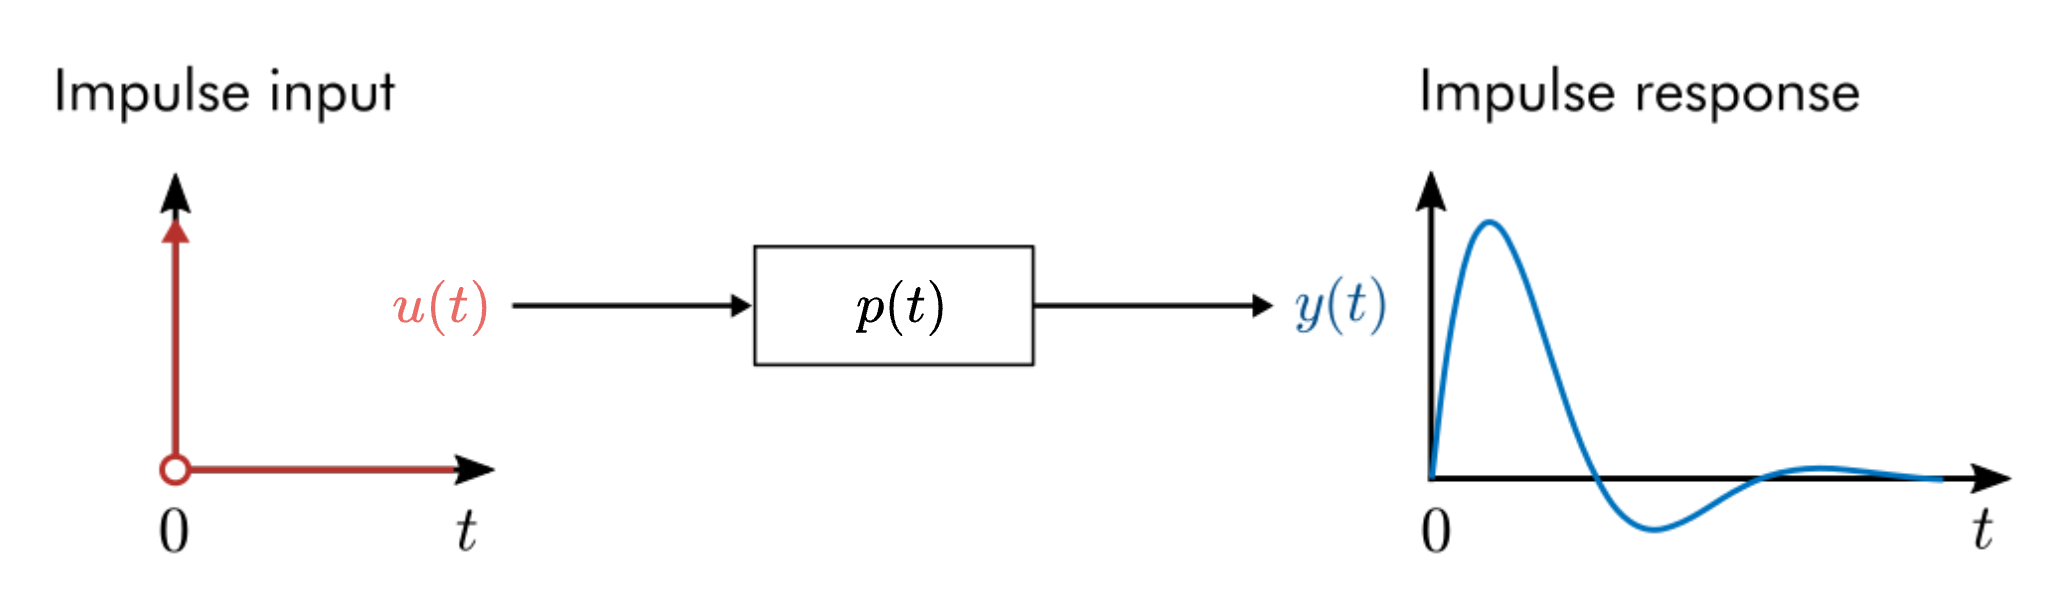

Here $\delta(t)$ is the Dirac delta function which has the properties:

    $\int_{-\infty}^{\infty} \delta(t) dt = 1 $   and   $\delta(t) = 0 \text{ for } t \neq 0$

Think of the unit impulse as giving the system a (very) quick shove at time $t=0$. The impulse response shows how the system will respond to that shove. This mathematical formulation is convenient because the output becomes $y(t)=p(t)$, which exactly describes the model of the system directly.

#### **  Question 2: **Given that $y(t)=p(t)$, and by implication $Y(s)=P(s)$, what can you surmise is $\mathcal{L}\{u(t)\}=\mathcal{L}\{\delta(t)\}$?

To plot the impulse response in MATLAB, we can use the [`impulse`](https://www.mathworks.com/help/control/ref/lti.impulse.html) function as shown below.

m = 1; %mass, in kg
c = 0.1; %damping coefficient, in Ns/m
k = 0.4; %spring constant, in N/m

s = tf('s'); %this defines the Laplace variable s.
P = 1/(m*s^2+c*s+k) %transfer function of our mass-spring-damper system

[y,t] = impulse(P); %applies an impulse input to P(s) and then generates the resulting y(t)

figure
plot(t,y,lineWidth=2)
grid on
xlabel('time (s)')  %adds a label to the x-axis
ylabel('Position (m)') %adds a label to the y-axis
title('Impulse response of mass-spring-damper system') %adds/changes the title of a figure
axis tight

This natural response of the system can be used to infer information about the system. While this mathematical formulation is appealing, applying an impulse signal in reality is impossible. This is because the magnitude of $\delta(t)$ is required to be infinitely large and applied instantaneously at $t=0$, in order to satisfy the properties detailed above.

### Step response

The step input is a very useful type of signal that is used to assess the stability and performance of a system. Importantly, it gets around the issue of the impulse response not being realisable in general. It is formally defined as the Heaviside step function, $\sigma(t)$, in many mathematical textbooks. In essence, it is a signal that has a value of zero for all negative time ($t<0$) and one everywhere else ($t\geq 1$), namely


$$\sigma(t)=\left\{
        \begin{array}{ll}
           1, &  t \geq 0, \\
           0, & t < 0. \\
        \end{array}
    \right.$$


The output generated from a step input is known as the step response, with an example of the time-domain response shown below. 

    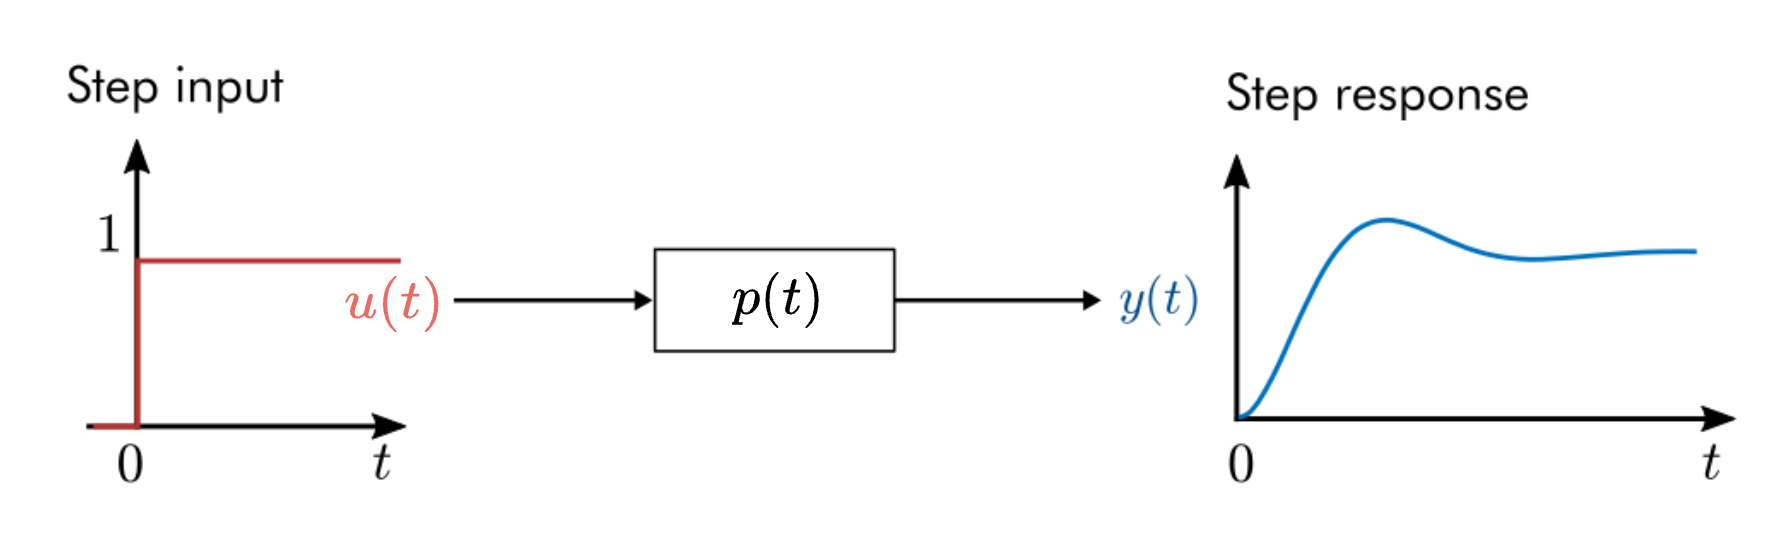

Think of the step response as the system's response to a sustained, instantaneous constant perturbation. In the case of the mass-spring-damper, a *negative* step input (having a value of -1 instead of 1 for $t\geq0$) would be the same as dropping an additional mass of 1 Newton on top of the mass-spring-damper and then seeing how the system responds.

The Laplace transform of a unit step input is 


$$U(s)=\mathcal{L}\{u(t)\}=\mathcal{L}\{\sigma(t)\}=\frac{1}{s}$$
 

and serves as a convenient way of deducing system information.

#### **  Question 3: **Using the Laplace transform above, if $P(s)=\frac{1}{ms^2+cs+k}$, what will the corresponding $Y(s)$ be when $u(t)=1$?

To plot the step response in `MATLAB`, we can use the [`step`](https://www.mathworks.com/help/control/ref/lti.step.html) function as shown below

m = 1; %mass, in kg
c = 0.1; %damping coefficient, in Ns/m
k = 0.4; %spring constant, in N/m

s = tf('s'); %this defines the Laplace variable s.
P = 1/(m*s^2+c*s+k) %transfer function of our mass-spring-damper system

[y,t] = step(P); %applies a step input to P(s) and then generates the resulting y(t)

figure
plot(t,y,lineWidth=2)
grid on
xlabel('time (s)')  %adds a label to the x-axis
ylabel('Position (m)') %adds a label to the y-axis
title('Step response of mass-spring-damper system') %adds/changes the title of a figure
axis tight

The response to the step input is oscillatory, but the position of the mass settles on a finite value of $y(t_\infty)=2.5$m, suggesting that it appears to be stable (the signal is not growing without bound).

To get a better feel for how the mass-spring-damper parameters affects the system response, we can make use of numeric sliders to adjust the parameters and then see the resulting response (the sliders are setup such that adjusting any slider will rerun this section of code). We are also going to use a helper function, `animateSingleMSD,` that creates a simple animation of the mass-spring-damper (*you do not need to worry about how this function works!)*.

m = 4; 
c = 0.1;
k = 0.8;

s= tf('s')
P = 1/(m*s^2+c*s+k)

[y,t] = step(P); %applies a step input to G(s) and then generates the resulting y(t)
u = heaviside(t); %generates the step input signal, u(t), with the same length as the output signal, y(t)
animateSingleMSD(t,y,u,0.5,150) %creates an animation that plots alongside u(t) and y(t)

Play around with the sliders above to see how it affects the system response. Take note of the oscillatory behaviour, rate at which the signal reaches its final value, and the value of the steady-state position.

#### **  Question 4: **What effect does changing $c$ have on the oscillations in the step response?

#### **  Question 5: **What value of $k$ is required for the steady-state (final) position to equal 1?

### Properties of Laplace transforms

Laplace transforms have several important properties that can be derived from the definition. A few essential properties are reviewed below.

    
$$\left.
\begin{array}{lll}
\textbf{Name} & \textbf{Time domain signal} & \textbf{Laplace doman signal}
\\
\text{Time derivative} \quad& \dot{f}(t) \quad & sF(s) - f(0)
\\
n^{th}~ \text{time derivative} \quad& \frac{d^n}{dt^n}f(t) \quad & s^nF(s)-\sum_{k=1}^ns^{n-k}f^{k-1}(0)
\\
\text{Time integral} \quad& \int_0^t f(\tau) d\tau \quad & \frac{F(s)}{s}
\\
\text{Frequency shift} \quad& e^{at} f(t) \quad & F(s-a)
\\
\text{Time shift} \quad& f(t-\tau) \quad & e^{-\tau s} F(s)
\\
\text{Time scaling} \quad& f(at) \quad & \frac{1}{a}F\left( \frac{s}{a}\right)
\\
\text{Time domain convolution} \quad &  f(t)*g(t) & F(s) G(s)
\\
\text{Homogeneous} \quad &  kf(t) & kF(s)
\\
\text{Additive} \quad &  f_1(t)+f_2(t) & F_1(s)+F_2(s)
\end{array}
\right.
$$


#### Time derivative

Assuming all initial conditions are equal to zero, we have the simply relationship

$\mathcal{L}\{\frac{df(t)}{dt}\}=sF(s)$.

Based on the relationship above, we should be able to see that the unit impulse, $\delta(t)$, is related to the unit step, $\sigma(t)$, by

$\mathcal{L}\{\delta(t)\}=\mathcal{L}\{\dot{\sigma}(t)\}=s\frac{1}{s}=1$.

In other words, the unit impulse function is equal to the derivative of the unit step function. The code below plots both the step and impulse response of our system. The two responses are related in a similar manner to that of the input signals.

m = 10; 
c = 0.7;
k = 0.8;

s = tf('s'); %this defines the Laplace variable s.
P = 1/(m*s^2+c*s+k); %transfer function of our mass-spring-damper system

figure
hold on %this function makes it so that you can make multiple plots on the same figure
[y,t] = step(P); 
plot(t,y,'b',lineWidth=2)
[y,t] = impulse(P); 
plot(t,y,'r',lineWidth=2)
grid on
xlabel('time (s)')  %adds a label to the x-axis
ylabel('Position (m)') %adds a label to the y-axis
title('Step response of mass-spring-damper system') %adds/changes the title of a figure
axis tight

#### **  Question 6: **What is the relationship between the unit step response and impulse response?

#### Time shift

Consider the **time shift **property above. Given a function $f(t)$, where $f(t)=0,\forall t<0$, the corresponding Laplace transfom is known to be $F(s) = \mathcal{L}\{f(t)\}$. If this function is now shifted in time by $\tau$ seconds, then only the phase angle of the Laplace transform is affected. Mathematically this is represented as

$\mathcal{L}\{f(t-\tau)\}=e^{-s\tau}\mathcal{L}\{f(t)\}=e^{-s\tau}F(s)$.

For example, a unit step signal, with time delay is represented as


$$\sigma(t-\tau)=\left\{
        \begin{array}{ll}
           1, &  t \geq \tau, \\
           0, & t < \tau. \\
        \end{array}
    \right.$$


The Laplace transform, based on the definition above, is


$$\begin{array}{ll}
\sigma(s) &= \frac{1}{s}e^{-s\tau},
\end{array}$$


where $\tau>0$ for causality (more on this later). The time shift property is demonstrated above based on a *signal* that is delayed in time, but we can also apply this same construct to *systems. *That is, a system with delay will only respond to an input signal $\tau$ seconds after the input signal has been applied. If our mass-spring-damper has delay, then we can represent our transfer function description as

$P(s)=\frac{1}{ms^2+cs+k}e^{-s\tau}$.

Note that when we apply an input signal (without delay), then the output signal will respond with delay as a result of the $e^{-s\tau}$ term, namely

$Y(s)=P(s)U(s)=\frac{1}{ms^2+cs+k}U(s)e^{-s\tau}$.

####   **Task:** Edit the code below so that *two* unit step responses are plotted on the same figure. One with no delay (plotted in blue), and one with a delay of $\tau=5$ seconds (plotted in red).

m = 2;
c = 0.8;
k = 1;

s = tf('s'); %this defines the Laplace variable s.
P = 1/(m*s^2+c*s+k); %transfer function of our mass-spring-damper system

figure
hold on %this function makes it so that you can make multiple plots on the same figure
[y,t] = step(P); 
plot(t,y,'b',lineWidth=2)
grid on
xlabel('time (s)')  %adds a label to the x-axis
ylabel('Position (m)') %adds a label to the y-axis
title('Step response of mass-spring-damper system') %adds/changes the title of a figure
axis tight

####   Question 7: Upload an image of the generated figure as an image (PNG or JPEG). The title of the figure must be your student number.

#### **Homogeneity**

The Laplace transform of a scaled signal is equivalent to the Laplace transform of the signal without scaling, multiplied by the scaling factor. This is referred to as **homogeneity**.

$\mathcal{L} \{ kf(t) \}=k\mathcal{L} \{ f(t) \}=kF(s)$.

This property can also be extended to systems. Specifically, if a system is linear, then scaling the input signal by some amount should result in the output signal also being scaled by the same amount.

####   **Task:** Edit the code below so that the step responses of $U_1(s)=\frac{1}{s}$ and $U_2(s)=-\frac{1}{s}$ are plotted on the same figure. $Y_1(s)$ must be plotted in blue, and $Y_2(s)$ must be plotted in red.

m = 2;
c = 0.8;
k = 1;

s = tf('s'); %this defines the Laplace variable s.
P = 1/(m*s^2+c*s+k); %transfer function of our mass-spring-damper system

figure
hold on %this function makes it so that you can make multiple plots on the same figure
[y,t] = step(P); 
plot(t,y,'b',lineWidth=2)
grid on
xlabel('time (s)')  %adds a label to the x-axis
ylabel('Position (m)') %adds a label to the y-axis
title('Step response of mass-spring-damper system') %adds/changes the title of a figure
axis tight

####   Question 8: Upload an image of the generated figure as an image (PNG or JPEG). The title of the figure must be your student number.

### Block diagram of mass-spring-damper

The mass-spring-damper system can also be modelled as a block diagram (as can any linear system). The block diagram below represents our system under consideration. Note that time-domain signals are indicated, but the signal-system multiplication makes use of the corresponding Laplace domain signals.

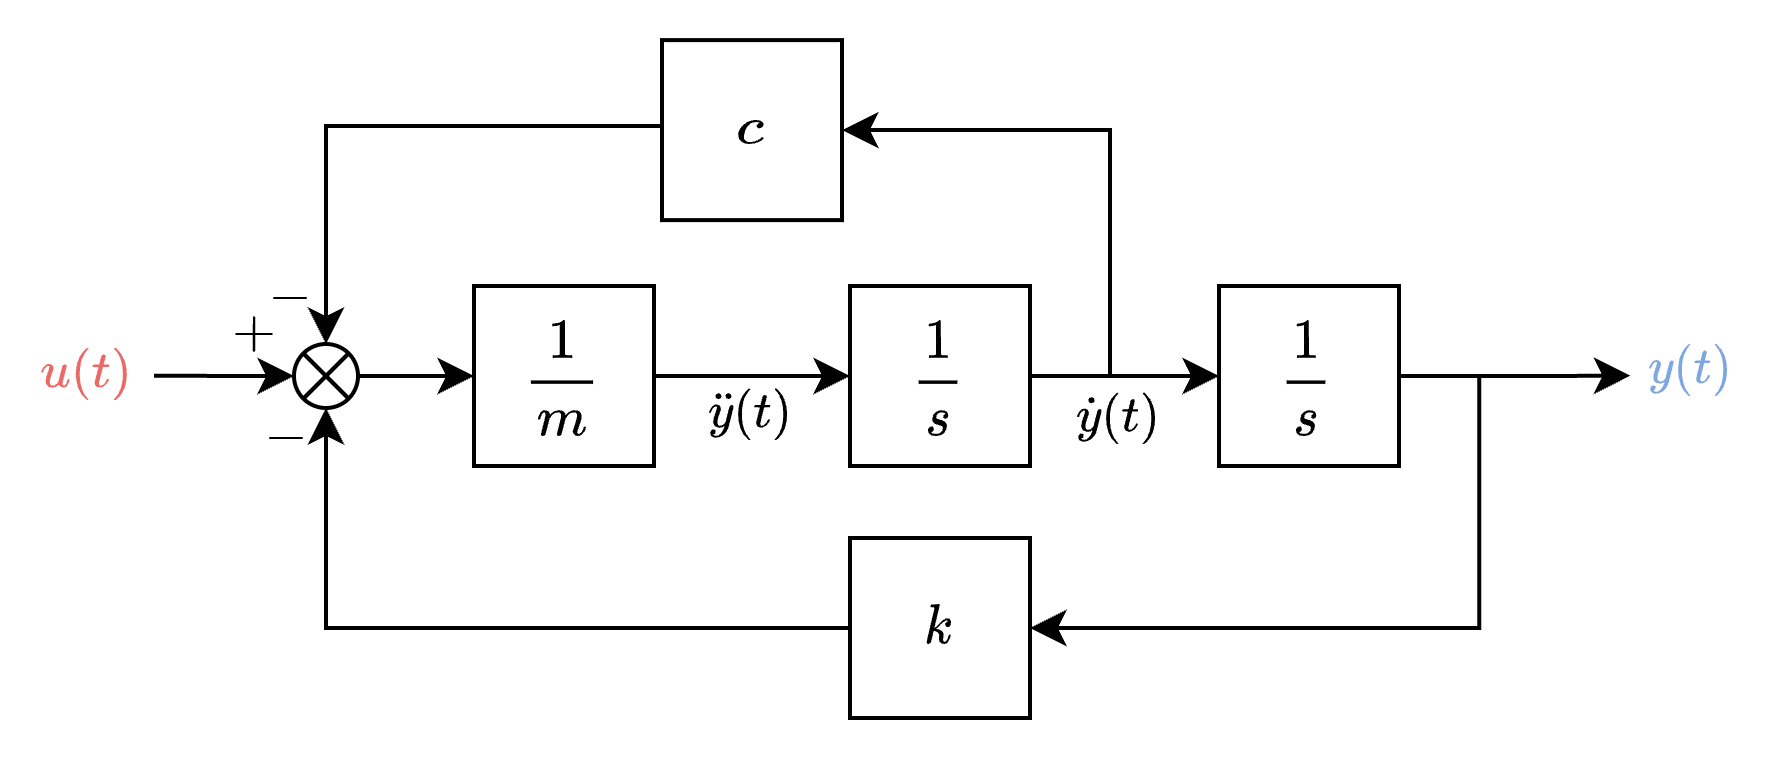

#### **  Question 9: Use block diagram reduction to show that **$P(s)=\frac{Y(s)}{U(s)}=\frac{1}{ms^2+cs+k}$. Show all working.

#### **  Question 10: Rename your completed live script to include your student number (e.g. VirtualLab1_SMTJOH999.mlx) and submit it as your answer to Question 10.**

***This concluded Virtual Lab 1.***

### **Helper functions **

*You do not neeed to understand this, but it may be of interest to you.*

function animateSingleMSD(tin,xin,uin,w,Npoints)
% Generates an animation of a single mass/spring/damper
% t: time array
% x: displacement array
% w: width of the mass

% Interpolate to Npoints
t = linspace(tin(1),tin(end),Npoints);
x = interp1(tin,xin,t);
u = interp1(tin,uin,t);

colors = lines(6);
fs = 14;

% Create plot
k = 1;
figure("position",[0 0 1500 400]);

% Setup the figure
buffer = 1.2;
xrange = max(x) - min(x);
xmax = min(x) + xrange*buffer ;
xmin = max(x) - xrange*buffer - w*1.5;
tlim = [t(1) t(end)];
axisLim1 = [tlim(1),tlim(2),xmin,xmax];
axisLim2 = [-w*buffer,w*buffer,xmin,xmax];
xground = xmin;

subplot(1,3,1);
plot(tin,uin,"color",[0.7176 0.1922 0.1725],"linewidth",1.5)
xlabel("$t$ [s]","Interpreter","latex","FontSize",fs)
ylabel("$u(t)$ [N]","Interpreter","latex","FontSize",fs)
box off
axis([t(1),t(end),min(u)-0.2,max(u)+0.2])
title("Input function")

subplot(1,3,2);
set(gca, "Clipping","off","Color","none");
hold on
plot(tin,xin,"k-","color",colors(1,:),"linewidth",1.5);
a = plot([0, tlim(2)+(tlim(2)-tlim(1))*4], [x(k),x(k)],"-","color",[colors(4,:),0.5],"linewidth",1.5);
b = plot(t(k),x(k),"o","markerfacecolor",colors(2,:),"MarkerSize",8);
hold off
axis(axisLim1)
box off
xlabel("$t$ [s]","Interpreter","latex","FontSize",fs)
ylabel("$x$ [m]","Interpreter","latex","FontSize",fs)
title("displacement response")

subplot(1,3,3);
set(gca, "Clipping","off","Color","none");
hold on
plot([-w*buffer w*buffer],[xground xground],'k-',"linewidth",1.5);
% Plot mass
x1 = x(k) - w/2;
c = rectangle("Position",[-w/2 x1-w w w],"FaceColor",colors(1,:));
% Plot spring
xextension = x(k)-w;
xs = linspace(xground,xextension,12);
ys = w/6*(-1).^(1:numel(xs)) - w/4;
d = plot(ys,xs,"k","linewidth",1.5);
% Plot damper
ydamp = w/4;
xdamp1 = xground + (xextension-xground)/2 + w*0.1;
xdamp2 = xground + (xextension-xground)/2;
xdamp3 = xground + (xextension-xground)/2 + w*0.2;
e = plot([ydamp,ydamp,NaN,ydamp-w/10,ydamp+w/10],[xground,xdamp1,NaN,xdamp1,xdamp1],"k","linewidth",1.5);
f = plot([ydamp-w*0.15,ydamp-w*0.15,NaN,ydamp+w*0.15,ydamp+w*0.15,NaN,ydamp-w*0.15,ydamp+w*0.15,NaN,ydamp,ydamp],...
    [xdamp2,xdamp3,NaN,xdamp2,xdamp3,NaN,xdamp3,xdamp3,NaN,xdamp3,xextension],"k","linewidth",1.5);

hold off
axis equal
axis(axisLim2)
ax = gca;
ax.XAxis.Visible = 'off';
title("diagram")

% Create animation
for k = 1:length(t)
    % displacement
    a.YData = [x(k),x(k)];
    b.XData = t(k);
    b.YData = x(k);
    % mass
    c.Position = [-w/2,x(k)-w,w,w];
    xextension = x(k)-w;
    % spring
    d.YData = linspace(xground,xextension,12);
    % damper
    xdamp1 = xground + (xextension-xground)/2 + w*0.1;
    xdamp2 = xground + (xextension-xground)/2;
    xdamp3 = xground + (xextension-xground)/2 + w*0.2;
    e.YData = [xground xdamp1 NaN xdamp1 xdamp1];
    f.YData = [xdamp2 xdamp3 NaN xdamp2 xdamp3 NaN xdamp3 xdamp3 NaN xdamp3 xextension];
    pause(0)
    drawnow
end
drawnow
close all
end